# Quadcopter Dynamics

% State Variables
syms x y z x_dot y_dot z_dot % position & derivatives
syms phi theta psi phi_dot theta_dot psi_dot % euler angular & derivatives
syms w_b [1 3] % rotational velocity of body
syms T [1 4]   % Thrust due to motor
syms M [1 4]   % Moment due to motor
syms S_T Mx My Mz % sum thrust, Moments
syms w_m [1 4] % motor angular velocities
syms p s r p_dot s_dot r_dot % rotational values
syms U % Input vector of torques and moments

% System Properties
syms I_xx I_xy I_xz I_yy I_yz I_zz   % Body Inertia Matrix
syms k_t k_m     % Propeller Coeff
syms blade_pos_body [4 3] % Rotor positions
syms b_w b_l a_l  % refer to image, body and arm dim
syms g m

## Defining Rotation Matrices and State vector

R3 = [cos(psi) sin(psi) 0; -sin(psi) cos(psi) 0; 0 0 1]

$$R3 = \left(\begin{array}{ccc} \cos\left(\psi \right) & \sin\left(\psi \right) & 0\\ -\sin\left(\psi \right) & \cos\left(\psi \right) & 0\\ 0 & 0 & 1 \end{array}\right)$$

R2 = [cos(theta ) 0 -sin(theta ); 0 1 0; sin(theta ) 0 cos(theta )]

$$R2 = \left(\begin{array}{ccc} \cos\left(\theta \right) & 0 & -\sin\left(\theta \right)\\ 0 & 1 & 0\\ \sin\left(\theta \right) & 0 & \cos\left(\theta \right) \end{array}\right)$$

R1 = [1 0 0;0 cos(phi ) sin(phi );0 -sin(phi ) cos(phi )]

$$R1 = \left(\begin{array}{ccc} 1 & 0 & 0\\ 0 & \cos\left(\varphi \right) & \sin\left(\varphi \right)\\ 0 & -\sin\left(\varphi \right) & \cos\left(\varphi \right) \end{array}\right)$$


% First Rotation R3, then 2 then 1 by definition of yaw pitch roll
Base_2_Body_Rot = R1 * R2 * R3

$$Base\_2\_Body\_Rot = \left(\begin{array}{ccc} \cos\left(\psi \right)\,\cos\left(\theta \right) & \cos\left(\theta \right)\,\sin\left(\psi \right) & -\sin\left(\theta \right)\\ \cos\left(\psi \right)\,\sin\left(\varphi \right)\,\sin\left(\theta \right)-\cos\left(\varphi \right)\,\sin\left(\psi \right) & \cos\left(\varphi \right)\,\cos\left(\psi \right)+\sin\left(\varphi \right)\,\sin\left(\psi \right)\,\sin\left(\theta \right) & \cos\left(\theta \right)\,\sin\left(\varphi \right)\\ \sin\left(\varphi \right)\,\sin\left(\psi \right)+\cos\left(\varphi \right)\,\cos\left(\psi \right)\,\sin\left(\theta \right) & \cos\left(\varphi \right)\,\sin\left(\psi \right)\,\sin\left(\theta \right)-\cos\left(\psi \right)\,\sin\left(\varphi \right) & \cos\left(\varphi \right)\,\cos\left(\theta \right) \end{array}\right)$$

Body_2_Base_Rot = Base_2_Body_Rot.'

$$Body\_2\_Base\_Rot = \left(\begin{array}{ccc} \cos\left(\psi \right)\,\cos\left(\theta \right) & \cos\left(\psi \right)\,\sin\left(\varphi \right)\,\sin\left(\theta \right)-\cos\left(\varphi \right)\,\sin\left(\psi \right) & \sin\left(\varphi \right)\,\sin\left(\psi \right)+\cos\left(\varphi \right)\,\cos\left(\psi \right)\,\sin\left(\theta \right)\\ \cos\left(\theta \right)\,\sin\left(\psi \right) & \cos\left(\varphi \right)\,\cos\left(\psi \right)+\sin\left(\varphi \right)\,\sin\left(\psi \right)\,\sin\left(\theta \right) & \cos\left(\varphi \right)\,\sin\left(\psi \right)\,\sin\left(\theta \right)-\cos\left(\psi \right)\,\sin\left(\varphi \right)\\ -\sin\left(\theta \right) & \cos\left(\theta \right)\,\sin\left(\varphi \right) & \cos\left(\varphi \right)\,\cos\left(\theta \right) \end{array}\right)$$


% State vector definition, splitting into logical parts
q1 = [x; y; z;]

$$q1 = \left(\begin{array}{c} x\\ y\\ z \end{array}\right)$$

q2 = [x_dot; y_dot; z_dot ;]

$$q2 = \left(\begin{array}{c} \dot{x}\\ \dot{y}\\ \dot{z} \end{array}\right)$$

q3 = [phi; theta; psi;]

$$q3 = \left(\begin{array}{c} \varphi \\ \theta \\ \psi \end{array}\right)$$

q3_dot = [phi_dot; theta_dot; psi_dot]

$$q3\_dot = \left(\begin{array}{c} \dot{\varphi }\\ \dot{\theta }\\ \dot{\psi } \end{array}\right)$$

q4 = [p; s; r]

$$q4 = \left(\begin{array}{c} p\\ s\\ r \end{array}\right)$$

q4_dot = [p_dot; s_dot; r_dot]

$$q4\_dot = \left(\begin{array}{c} \dot{p}\\ \dot{s}\\ \dot{r} \end{array}\right)$$

q = [q1;q2;q3;q4]

$$q = \left(\begin{array}{c} x\\ y\\ z\\ \dot{x}\\ \dot{y}\\ \dot{z}\\ \varphi \\ \theta \\ \psi \\ p\\ s\\ r \end{array}\right)$$


% Euler angle to rotational velocity matrix
w_2_euler = [1 sin(phi)*tan(theta) cos(phi)*tan(theta); 0 cos(phi) -sin(phi); 0 sin(phi)/cos(theta) cos(phi)/cos(theta)]

$$w\_2\_euler = \left(\begin{array}{ccc} 1 & \sin\left(\varphi \right)\,\tan\left(\theta \right) & \cos\left(\varphi \right)\,\tan\left(\theta \right)\\ 0 & \cos\left(\varphi \right) & -\sin\left(\varphi \right)\\ 0 & \frac{\sin\left(\varphi \right)}{\cos\left(\theta \right)} & \frac{\cos\left(\varphi \right)}{\cos\left(\theta \right)} \end{array}\right)$$

euler_2_w = inv(w_2_euler)

$$euler\_2\_w = \begin{array}{l} \left(\begin{array}{ccc} 1 & 0 & -\cos\left(\theta \right)\,\tan\left(\theta \right)\\ 0 & \frac{\cos\left(\varphi \right)}{\sigma_{1}} & \frac{\cos\left(\theta \right)\,\sin\left(\varphi \right)}{\sigma_{1}}\\ 0 & -\frac{\sin\left(\varphi \right)}{\sigma_{1}} & \frac{\cos\left(\varphi \right)\,\cos\left(\theta \right)}{\sigma_{1}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}={\cos\left(\varphi \right)}^{2}+{\sin\left(\varphi \right)}^{2} \end{array}$$

## Thrust and Moments produced by each motor


T1 = k_t * w_m1^2

$$T1 = k_{t}\,{w_{\mathrm{m1}}}^{2}$$

T2 = k_t * w_m2^2

$$T2 = k_{t}\,{w_{\mathrm{m2}}}^{2}$$

T3 = k_t * w_m3^2

$$T3 = k_{t}\,{w_{\mathrm{m3}}}^{2}$$

T4 = k_t * w_m4^2

$$T4 = k_{t}\,{w_{\mathrm{m4}}}^{2}$$


S_T = T1 + T2 + T3 + T4;

M1 = k_m * w_m1^2

$$M1 = k_{m}\,{w_{\mathrm{m1}}}^{2}$$

M2 = k_m * w_m2^2

$$M2 = k_{m}\,{w_{\mathrm{m2}}}^{2}$$

M3 = k_m * w_m3^2

$$M3 = k_{m}\,{w_{\mathrm{m3}}}^{2}$$

M4 = k_m * w_m4^2

$$M4 = k_{m}\,{w_{\mathrm{m4}}}^{2}$$

## Propeller Positions and Condensing to Torque and Moment Vector

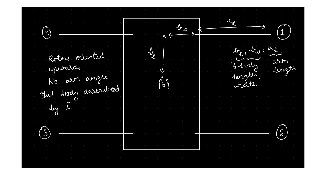

imshow(imread("drone_body_rough_wtf.png"))


blade_pos_body = [b_w + a_l b_l 0;b_w + a_l -b_l 0;-b_w - a_l -b_l 0;-b_w - a_l b_l 0;].'

$$blade\_pos\_body = \left(\begin{array}{cccc} a_{l}+b_{w} & a_{l}+b_{w} & -a_{l}-b_{w} & -a_{l}-b_{w}\\ b_{l} & -b_{l} & -b_{l} & b_{l}\\ 0 & 0 & 0 & 0 \end{array}\right)$$


H1 = cross(blade_pos_body(:, 1), [0; 0; T1])

$$H1 = \left(\begin{array}{c} b_{l}\,k_{t}\,{w_{\mathrm{m1}}}^{2}\\ -k_{t}\,{w_{\mathrm{m1}}}^{2}\,\left(a_{l}+b_{w}\right)\\ 0 \end{array}\right)$$

H2 = cross(blade_pos_body(:, 2), [0; 0; T2])

$$H2 = \left(\begin{array}{c} -b_{l}\,k_{t}\,{w_{\mathrm{m2}}}^{2}\\ -k_{t}\,{w_{\mathrm{m2}}}^{2}\,\left(a_{l}+b_{w}\right)\\ 0 \end{array}\right)$$

H3 = cross(blade_pos_body(:, 3), [0; 0; T3])

$$H3 = \left(\begin{array}{c} -b_{l}\,k_{t}\,{w_{\mathrm{m3}}}^{2}\\ k_{t}\,{w_{\mathrm{m3}}}^{2}\,\left(a_{l}+b_{w}\right)\\ 0 \end{array}\right)$$

H4 = cross(blade_pos_body(:, 4), [0; 0; T4])

$$H4 = \left(\begin{array}{c} b_{l}\,k_{t}\,{w_{\mathrm{m4}}}^{2}\\ k_{t}\,{w_{\mathrm{m4}}}^{2}\,\left(a_{l}+b_{w}\right)\\ 0 \end{array}\right)$$


H = H1 + H2 + H3 + H4

$$H = \left(\begin{array}{c} b_{l}\,k_{t}\,{w_{\mathrm{m1}}}^{2}-b_{l}\,k_{t}\,{w_{\mathrm{m2}}}^{2}-b_{l}\,k_{t}\,{w_{\mathrm{m3}}}^{2}+b_{l}\,k_{t}\,{w_{\mathrm{m4}}}^{2}\\ -k_{t}\,\left(a_{l}+b_{w}\right)\,{w_{\mathrm{m1}}}^{2}-k_{t}\,\left(a_{l}+b_{w}\right)\,{w_{\mathrm{m2}}}^{2}+k_{t}\,\left(a_{l}+b_{w}\right)\,{w_{\mathrm{m3}}}^{2}+k_{t}\,\left(a_{l}+b_{w}\right)\,{w_{\mathrm{m4}}}^{2}\\ 0 \end{array}\right)$$


Mx = H(1)

$$Mx = b_{l}\,k_{t}\,{w_{\mathrm{m1}}}^{2}-b_{l}\,k_{t}\,{w_{\mathrm{m2}}}^{2}-b_{l}\,k_{t}\,{w_{\mathrm{m3}}}^{2}+b_{l}\,k_{t}\,{w_{\mathrm{m4}}}^{2}$$

My = H(2)

$$My = -k_{t}\,\left(a_{l}+b_{w}\right)\,{w_{\mathrm{m1}}}^{2}-k_{t}\,\left(a_{l}+b_{w}\right)\,{w_{\mathrm{m2}}}^{2}+k_{t}\,\left(a_{l}+b_{w}\right)\,{w_{\mathrm{m3}}}^{2}+k_{t}\,\left(a_{l}+b_{w}\right)\,{w_{\mathrm{m4}}}^{2}$$

Mz = M1 + M2 + M3 + M4

$$Mz = k_{m}\,{w_{\mathrm{m1}}}^{2}+k_{m}\,{w_{\mathrm{m2}}}^{2}+k_{m}\,{w_{\mathrm{m3}}}^{2}+k_{m}\,{w_{\mathrm{m4}}}^{2}$$


U = [S_T; Mx; My; Mz]

$$U = \left(\begin{array}{c} k_{t}\,{w_{\mathrm{m1}}}^{2}+k_{t}\,{w_{\mathrm{m2}}}^{2}+k_{t}\,{w_{\mathrm{m3}}}^{2}+k_{t}\,{w_{\mathrm{m4}}}^{2}\\ b_{l}\,k_{t}\,{w_{\mathrm{m1}}}^{2}-b_{l}\,k_{t}\,{w_{\mathrm{m2}}}^{2}-b_{l}\,k_{t}\,{w_{\mathrm{m3}}}^{2}+b_{l}\,k_{t}\,{w_{\mathrm{m4}}}^{2}\\ -k_{t}\,\left(a_{l}+b_{w}\right)\,{w_{\mathrm{m1}}}^{2}-k_{t}\,\left(a_{l}+b_{w}\right)\,{w_{\mathrm{m2}}}^{2}+k_{t}\,\left(a_{l}+b_{w}\right)\,{w_{\mathrm{m3}}}^{2}+k_{t}\,\left(a_{l}+b_{w}\right)\,{w_{\mathrm{m4}}}^{2}\\ k_{m}\,{w_{\mathrm{m1}}}^{2}+k_{m}\,{w_{\mathrm{m2}}}^{2}+k_{m}\,{w_{\mathrm{m3}}}^{2}+k_{m}\,{w_{\mathrm{m4}}}^{2} \end{array}\right)$$


motorw_2_forces = [k_t k_t k_t k_t;b_l*k_t -b_l*k_t -b_l*k_t b_l*k_t;-k_t*(a_l + b_w) -k_t*(a_l + b_w) k_t*(a_l + b_w) k_t*(a_l + b_w);k_m k_m k_m k_m]

$$motorw\_2\_forces = \left(\begin{array}{cccc} k_{t} & k_{t} & k_{t} & k_{t}\\ b_{l}\,k_{t} & -b_{l}\,k_{t} & -b_{l}\,k_{t} & b_{l}\,k_{t}\\ -k_{t}\,\left(a_{l}+b_{w}\right) & -k_{t}\,\left(a_{l}+b_{w}\right) & k_{t}\,\left(a_{l}+b_{w}\right) & k_{t}\,\left(a_{l}+b_{w}\right)\\ k_{m} & k_{m} & k_{m} & k_{m} \end{array}\right)$$

## Forces and Moments on the Quadcopter

env_gravity_base = [0; 0; -g ]

$$env\_gravity\_base = \left(\begin{array}{c} 0\\ 0\\ -g \end{array}\right)$$

q1_ddot = 1/m *(env_gravity_base + Body_2_Base_Rot * ([0; 0; S_T]))

$$q1\_ddot = \begin{array}{l} \left(\begin{array}{c} \frac{\left(\sin\left(\varphi \right)\,\sin\left(\psi \right)+\cos\left(\varphi \right)\,\cos\left(\psi \right)\,\sin\left(\theta \right)\right)\,\sigma_{1}}{m}\\ -\frac{\left(\cos\left(\psi \right)\,\sin\left(\varphi \right)-\cos\left(\varphi \right)\,\sin\left(\psi \right)\,\sin\left(\theta \right)\right)\,\sigma_{1}}{m}\\ -\frac{g-\cos\left(\varphi \right)\,\cos\left(\theta \right)\,\sigma_{1}}{m} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=k_{t}\,{w_{\mathrm{m1}}}^{2}+k_{t}\,{w_{\mathrm{m2}}}^{2}+k_{t}\,{w_{\mathrm{m3}}}^{2}+k_{t}\,{w_{\mathrm{m4}}}^{2} \end{array}$$


% Full form inertia matrix should ?
% I_mat = [I_xx -I_xy -I_xz; -I_xy I_yy -I_yz; -I_xz -I_yz I_zz]
I_mat = [I_xx 0 0; 0 I_yy 0; 0 0 I_zz]

$$I\_mat = \left(\begin{array}{ccc} I_{\mathrm{xx}} & 0 & 0\\ 0 & I_{\mathrm{yy}} & 0\\ 0 & 0 & I_{\mathrm{zz}} \end{array}\right)$$

q4 = w_2_euler \ q3_dot

$$q4 = \left(\begin{array}{c} \dot{\varphi }-\dot{\psi }\,\cos\left(\theta \right)\,\tan\left(\theta \right)\\ \frac{\dot{\theta }\,\cos\left(\varphi \right)+\dot{\psi }\,\cos\left(\theta \right)\,\sin\left(\varphi \right)}{{\cos\left(\varphi \right)}^{2}+{\sin\left(\varphi \right)}^{2}}\\ -\frac{\dot{\theta }\,\sin\left(\varphi \right)-\dot{\psi }\,\cos\left(\varphi \right)\,\cos\left(\theta \right)}{{\cos\left(\varphi \right)}^{2}+{\sin\left(\varphi \right)}^{2}} \end{array}\right)$$

q4 = [p;s;r ]

$$q4 = \left(\begin{array}{c} p\\ s\\ r \end{array}\right)$$

q4_dot = [p_dot; s_dot; r_dot]

$$q4\_dot = \left(\begin{array}{c} \dot{p}\\ \dot{s}\\ \dot{r} \end{array}\right)$$

q4_dot = inv(I_mat) * (-cross(q4, I_mat * q4) + [Mx; My;Mz])

$$q4\_dot = \left(\begin{array}{c} \frac{b_{l}\,k_{t}\,{w_{\mathrm{m1}}}^{2}-b_{l}\,k_{t}\,{w_{\mathrm{m2}}}^{2}-b_{l}\,k_{t}\,{w_{\mathrm{m3}}}^{2}+b_{l}\,k_{t}\,{w_{\mathrm{m4}}}^{2}+I_{\mathrm{yy}}\,r\,s-I_{\mathrm{zz}}\,r\,s}{I_{\mathrm{xx}}}\\ -\frac{k_{t}\,\left(a_{l}+b_{w}\right)\,{w_{\mathrm{m1}}}^{2}+k_{t}\,\left(a_{l}+b_{w}\right)\,{w_{\mathrm{m2}}}^{2}-k_{t}\,\left(a_{l}+b_{w}\right)\,{w_{\mathrm{m3}}}^{2}-k_{t}\,\left(a_{l}+b_{w}\right)\,{w_{\mathrm{m4}}}^{2}+I_{\mathrm{xx}}\,p\,r-I_{\mathrm{zz}}\,p\,r}{I_{\mathrm{yy}}}\\ \frac{k_{m}\,{w_{\mathrm{m1}}}^{2}+k_{m}\,{w_{\mathrm{m2}}}^{2}+k_{m}\,{w_{\mathrm{m3}}}^{2}+k_{m}\,{w_{\mathrm{m4}}}^{2}+I_{\mathrm{xx}}\,p\,s-I_{\mathrm{yy}}\,p\,s}{I_{\mathrm{zz}}} \end{array}\right)$$